
clc;
clear;
close all;
[y,Fs]=audioread("music.au");
y=y';
%sound(y,Fs);

s1=f2_6(y);
%sound(s1,Fs);

lack of background music

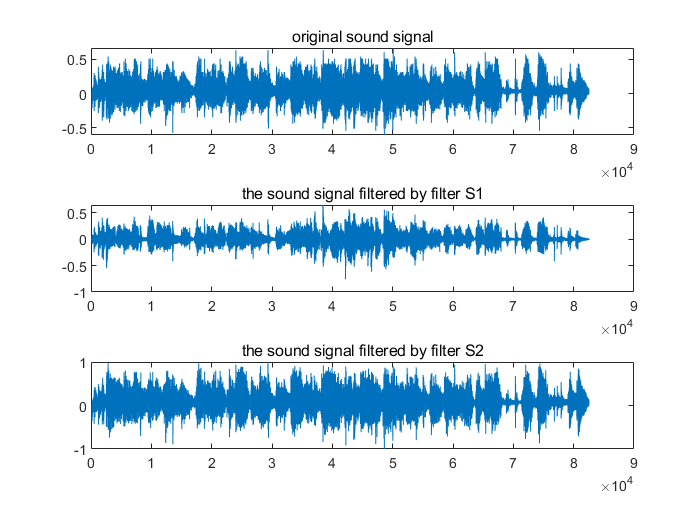

s2=f2_7(y);
%sound(s2,Fs);




figure;
subplot(3, 1, 1);
plot(y);
title('original sound signal');
subplot(3, 1, 2);
plot(s1);
title('the sound signal filtered by filter S1');
subplot(3, 1, 3);
plot(s2);
title('the sound signal filtered by filter S2');

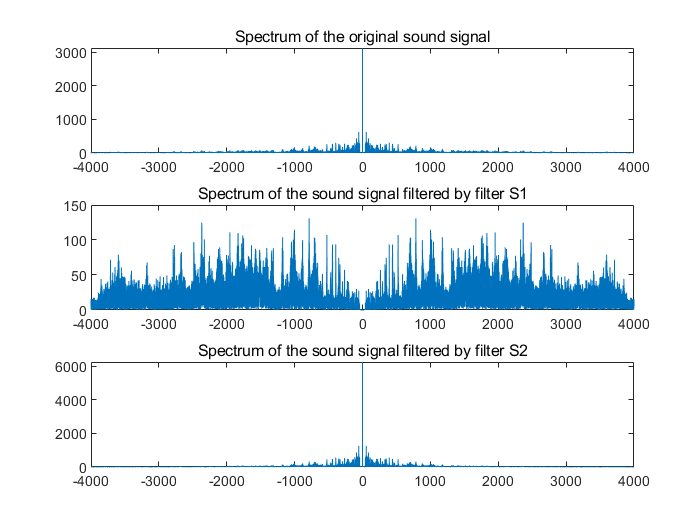



N = length(y); 


f = (-N/2:N/2-1)*(Fs/N); 
Y = abs(fftshift(fft(y))); 
S1 = abs(fftshift(fft(s1))); 
S2 = abs(fftshift(fft(s2))); 


figure;
subplot(3, 1, 1);
plot(f, Y);
title('Spectrum of the original sound signal');
subplot(3, 1, 2);
plot(f, S1);
title('Spectrum of the sound signal filtered by filter S1');
subplot(3, 1, 3);
plot(f, S2);
title('Spectrum of the sound signal filtered by filter S2');